**Porzione di piano compresa tra 4 curve.**

Innanzitutto, imposto gli intervalli in cui far variare le variabili.

x1=linspace(1.88, 3.2, 500)

x1 =     1.8800    1.8826    1.8853    1.8879    1.8906    1.8932    1.8959    1.8985    1.9012    1.9038    1.9065    1.9091    1.9117    1.9144    1.9170    1.9197    1.9223    1.9250    1.9276    1.9303    1.9329    1.9356    1.9382    1.9408    1.9435    1.9461    1.9488    1.9514    1.9541    1.9567    1.9594    1.9620    1.9646    1.9673    1.9699    1.9726    1.9752    1.9779    1.9805    1.9832    1.9858    1.9885    1.9911    1.9937    1.9964    1.9990    2.0017    2.0043    2.0070    2.0096


x2=linspace(1.07, 3.06, 500)

x2 =     1.0700    1.0740    1.0780    1.0820    1.0860    1.0899    1.0939    1.0979    1.1019    1.1059    1.1099    1.1139    1.1179    1.1218    1.1258    1.1298    1.1338    1.1378    1.1418    1.1458    1.1498    1.1537    1.1577    1.1617    1.1657    1.1697    1.1737    1.1777    1.1817    1.1857    1.1896    1.1936    1.1976    1.2016    1.2056    1.2096    1.2136    1.2176    1.2215    1.2255    1.2295    1.2335    1.2375    1.2415    1.2455    1.2495    1.2534    1.2574    1.2614    1.2654


theta=linspace(1, 3, 500)

theta =     1.0000    1.0040    1.0080    1.0120    1.0160    1.0200    1.0240    1.0281    1.0321    1.0361    1.0401    1.0441    1.0481    1.0521    1.0561    1.0601    1.0641    1.0681    1.0721    1.0762    1.0802    1.0842    1.0882    1.0922    1.0962    1.1002    1.1042    1.1082    1.1122    1.1162    1.1202    1.1242    1.1283    1.1323    1.1363    1.1403    1.1443    1.1483    1.1523    1.1563    1.1603    1.1643    1.1683    1.1723    1.1764    1.1804    1.1844    1.1884    1.1924    1.1964


aux1=linspace(0,1.88, 500)

aux1 =          0    0.0038    0.0075    0.0113    0.0151    0.0188    0.0226    0.0264    0.0301    0.0339    0.0377    0.0414    0.0452    0.0490    0.0527    0.0565    0.0603    0.0640    0.0678    0.0716    0.0754    0.0791    0.0829    0.0867    0.0904    0.0942    0.0980    0.1017    0.1055    0.1093    0.1130    0.1168    0.1206    0.1243    0.1281    0.1319    0.1356    0.1394    0.1432    0.1469    0.1507    0.1545    0.1582    0.1620    0.1658    0.1695    0.1733    0.1771    0.1808    0.1846


aux2=linspace(0,1.07, 500)

aux2 =          0    0.0021    0.0043    0.0064    0.0086    0.0107    0.0129    0.0150    0.0172    0.0193    0.0214    0.0236    0.0257    0.0279    0.0300    0.0322    0.0343    0.0365    0.0386    0.0407    0.0429    0.0450    0.0472    0.0493    0.0515    0.0536    0.0558    0.0579    0.0600    0.0622    0.0643    0.0665    0.0686    0.0708    0.0729    0.0751    0.0772    0.0793    0.0815    0.0836    0.0858    0.0879    0.0901    0.0922    0.0943    0.0965    0.0986    0.1008    0.1029    0.1051


Definisco le funzioni

f1=ones(size(x1))

f1 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


f2=cos(0.5*theta)+1

f2 =     1.8776    1.8766    1.8757    1.8747    1.8737    1.8727    1.8718    1.8708    1.8698    1.8688    1.8678    1.8668    1.8658    1.8648    1.8638    1.8628    1.8618    1.8607    1.8597    1.8587    1.8577    1.8566    1.8556    1.8546    1.8535    1.8525    1.8514    1.8504    1.8493    1.8483    1.8472    1.8461    1.8451    1.8440    1.8429    1.8418    1.8407    1.8397    1.8386    1.8375    1.8364    1.8353    1.8342    1.8331    1.8320    1.8308    1.8297    1.8286    1.8275    1.8264


f3=3*ones(size(x2))

f3 =      3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3


f4=cos(0.5*theta+2)+4

f4 =     3.1989    3.1977    3.1965    3.1953    3.1941    3.1929    3.1917    3.1905    3.1894    3.1882    3.1870    3.1859    3.1847    3.1835    3.1824    3.1812    3.1801    3.1789    3.1778    3.1767    3.1755    3.1744    3.1733    3.1721    3.1710    3.1699    3.1688    3.1677    3.1666    3.1654    3.1643    3.1632    3.1622    3.1611    3.1600    3.1589    3.1578    3.1567    3.1556    3.1546    3.1535    3.1524    3.1514    3.1503    3.1493    3.1482    3.1472    3.1461    3.1451    3.1440


faux=ones(size(aux1))

faux =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


faux2=3*ones(size(aux2))

faux2 =      3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3


Avvio l'area per la figura

figure
hold on
liminf=0

liminf = 0

limsup=4

limsup = 4

axis([liminf limsup liminf limsup])

Traccio il grafico delle curve

plot(f1,x1, 'k')
plot(theta, f2, 'k')
plot(f3, x2,'k')
plot(theta, f4,'k')
plot(faux, aux1, '-- k')
plot(faux2, aux2, '-- k')

Calcolo la derivata di f2, f4

dy=-0.5*sin(0.5*theta)

dy =    -0.2397   -0.2406   -0.2415   -0.2423   -0.2432   -0.2441   -0.2450   -0.2458   -0.2467   -0.2476   -0.2485   -0.2493   -0.2502   -0.2511   -0.2519   -0.2528   -0.2537   -0.2545   -0.2554   -0.2562   -0.2571   -0.2580   -0.2588   -0.2597   -0.2605   -0.2614   -0.2622   -0.2631   -0.2639   -0.2648   -0.2656   -0.2665   -0.2673   -0.2682   -0.2690   -0.2699   -0.2707   -0.2716   -0.2724   -0.2732   -0.2741   -0.2749   -0.2758   -0.2766   -0.2774   -0.2783   -0.2791   -0.2799   -0.2807   -0.2816


dx=1

dx = 1

dy1=-0.5*sin(0.5*theta+2)

dy1 =    -0.2992   -0.2984   -0.2976   -0.2968   -0.2960   -0.2952   -0.2944   -0.2936   -0.2928   -0.2920   -0.2911   -0.2903   -0.2895   -0.2887   -0.2879   -0.2871   -0.2862   -0.2854   -0.2846   -0.2838   -0.2829   -0.2821   -0.2813   -0.2805   -0.2796   -0.2788   -0.2780   -0.2771   -0.2763   -0.2755   -0.2746   -0.2738   -0.2730   -0.2721   -0.2713   -0.2704   -0.2696   -0.2687   -0.2679   -0.2670   -0.2662   -0.2654   -0.2645   -0.2637   -0.2628   -0.2619   -0.2611   -0.2602   -0.2594   -0.2585


dx1=1

dx1 = 1

Inserisco i versi di percorrenza delle diverse curve

quiver(f1(1), x1(270), 0, -0.3, 'LineWidth', 1.5, 'MaxHeadSize', 1.5, 'Color', 'g')
quiver(theta(250), f2(250), 0.3*dx, 0.3*dy(250), 'LineWidth', 1.5, 'MaxHeadSize', 1.5, 'Color', 'g')
quiver(f3(1), x2(270), 0, 0.3, 'LineWidth', 1.5, 'MaxHeadSize', 1.5, 'Color', 'g')
quiver(theta(250), f4(250), -0.3*dx1, -0.3*dy1(250), 'LineWidth', 1.5, 'MaxHeadSize', 1.5, 'Color', 'g')

Poiché non necessari, rimuovo i numeri dagli assi. Poi rinomino i punti x=1 e x=3

xticks=[1,3]

xticks =      1     3


xtick_lab={'a', 'b'}

xtick_lab = 1×2 cell array
    {'a'}    {'b'}


set(gca, 'XTick', xticks, 'XTickLabel', xtick_lab)
set(gca, 'YTick', [])

Aggiungo etichette alle curve

text(3.3, 0.5*cos(1)+ 0.7, '$\alpha(x)$', 'Interpreter', 'latex', 'Color', 'k') 
text(3.3, 0.5*cos(3)+ 3.7, '$\beta(x)$', 'Interpreter', 'latex', 'Color', 'k') 
text(2, 0.5*cos(1)+1, '$\gamma_1$', 'Interpreter','latex', 'Color','k')
text(3.3, 1.07+(3.06-1.07)/2, '$\gamma_2$','Interpreter','latex', 'Color','k')
text(2, 0.5*cos(3)+3.7, '$\gamma_3$', 'Interpreter','latex', 'Color','k')
text(0.7, 1.88+(3.2-1.88)/2, '$\gamma_4$','Interpreter','latex', 'Color','k')

Chiudo il tutto

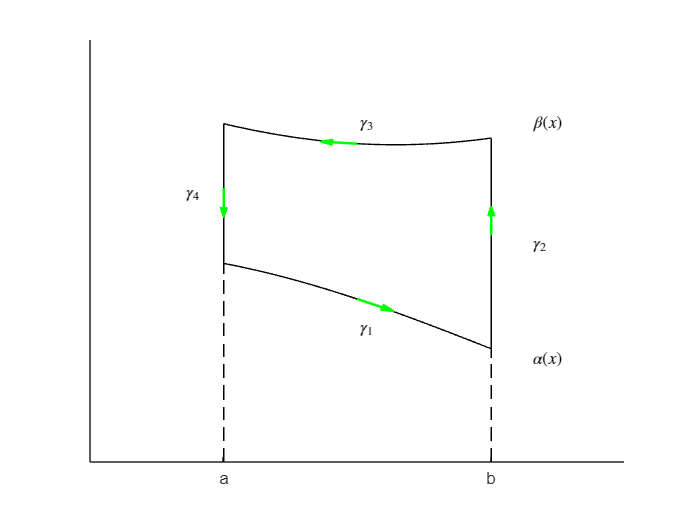

hold off